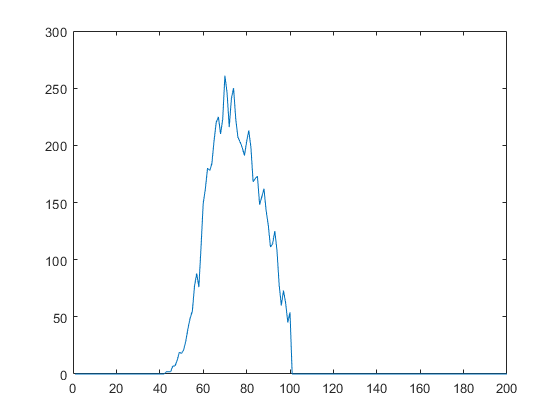

samples = [];
sample_dist = zeros(1,2000);
for smp = 1:4000
    key_num = 800;
    card = gene_HLL(key_num);
    samples = [samples,card];
    sample_dist(uint32(card)) = sample_dist(uint32(card)) + 1;
end
aggr_sample_dist = zeros(1,200);
for i = 0:99
    for j = 1:20
        aggr_sample_dist(1,i+1) = aggr_sample_dist(1,i+1) + ...
        sample_dist(1,i*10+j);
    end
end
plot(aggr_sample_dist);

function card = gene_HLL(true_card)
    HLL_arr = zeros(1,32);
    for i = 1:true_card
        pos = mod(uint32(floor(rand() * 4294967295)),32) + 1;
        tmpv = lzeros() + 1;
        HLL_arr(1,pos) = max(HLL_arr(1,pos),tmpv);
    end
    card = calcHLL(HLL_arr);
end
function res = calcHLL(HLL_arr)
    arrlen = size(HLL_arr,2);
    sum_ = 0;
    for i = 1:arrlen
        sum_ = sum_ + 1 / bitshift(1,HLL_arr(1,i));
    end
    alpha_m_sqm = 0.673 * 32 * 32;
    res = alpha_m_sqm / sum_;
end
function z = lzeros()
    tmpv = uint32(floor(rand() * 4294967295)); 
    for j = 1:31
        if bitshift(bitshift(tmpv,j),-j) ~= tmpv
            z = j - 1;
            return;
        end
    end
end